close all;

% Read file
filename = "2015_pitches_excel4.csv";
tbl = readtable(filename,'TextType','String');
tblinput = normalize(tbl(:,1:end-1),'range',[1 2]);
tbl = [tblinput tbl(:,"Pitch_Type")];

% Create a column for each pitch type with binary
InputNames = ["Pitch_Type"];
tbl = convertvars(tbl,InputNames,'categorical');

for i = 1:numel(InputNames)
    name = InputNames(i);
    oh = onehotencode(tbl(:,name));
    tbl = addvars(tbl,oh,'After',name);
    tbl(:,name) = [];
end

tbl

tbl = 701281×10 table
    Score_Diff    Balls    Strikes    Outs    Pitch_Number    Runner_First    Runner_Second    Runner_Third    Half_Inning       oh    
    __________    _____    _______    ____    ____________    ____________    _____________    ____________    ___________    _________

         1.5         1         1        1             1            1                1               1               1         1×8 table
         1.5         1       1.5        1        1.0714            1                1               1               1         1×8 table
         1.5         1         2        1        1.1429            1                1        

% Split the columns and display a few rows of the table and pitch types
tbl = splitvars(tbl);
head(tbl)

    Score_Diff    Balls    Strikes    Outs    Pitch_Number    Runner_First    Runner_Second    Runner_Third    Half_Inning    1    2    3    4    5    6    7    8
    __________    _____    _______    ____    ____________    ____________    _____________    ____________    ___________    _    _    _    _    _    _    _    _

       1.5           1         1        1             1            1                1          

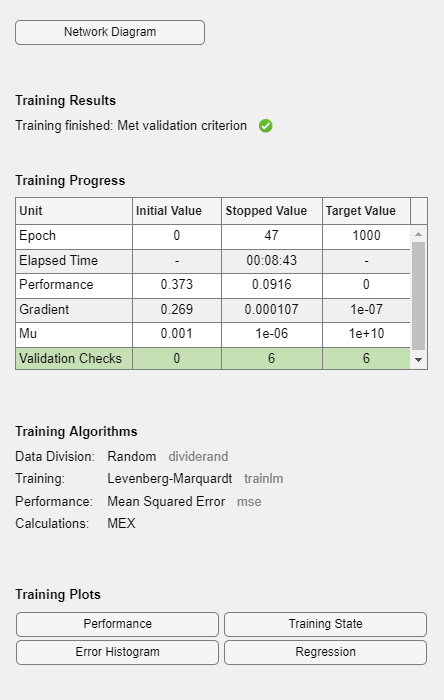

net =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 98
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inputConn

% Create feed forward network
x = table2array(tbl(:,1:9))';
t = table2array(tbl(:,10:17))';
net = feedforwardnet(5);
net = train(net,x,t)

% Test performance of the network
y = net(x);
e = gsubtract(t,y);
performance = perform(net,t,y)

performance = 0.0917

% Compute accuracy
for i = 1:size(tbl,1)
    for j=1:8
        if y(j,i) == max(y(:,i))
            y(j,i)=1;
        else
            y(j,i)=0;
        end
    end
end

[~, YPred] = max(y);
[~,Y] = max(t);

Accuracy = sum(YPred == Y)/numel(Y)

Accuracy = 0.4119


% Confusion matrix
C = confusionmat(Y,YPred)

C =       288063           0           0           0           0           0         471           0
      148854           0           0           0           0           0         256           0
       11214           0           0           0           0           0          13           0
      101814           0           0           0           0           0         100           0
       73916           0           0           0           0           0         103           0
       68797           0           0           0           0           0          41           0
        2822           0           0           0           0           0         775           0
        4036           0           0           0           0           0           6           0
